close all;
clear all;
clc;

s = tf('s');
sys = 1/(s^2 + 10*s + 20);

num_of_evolutions = 10;


pop = generateIntialPopulation(100, sys);

#### **Calculating kp,ki,kd using Ziegra Nichols method..**

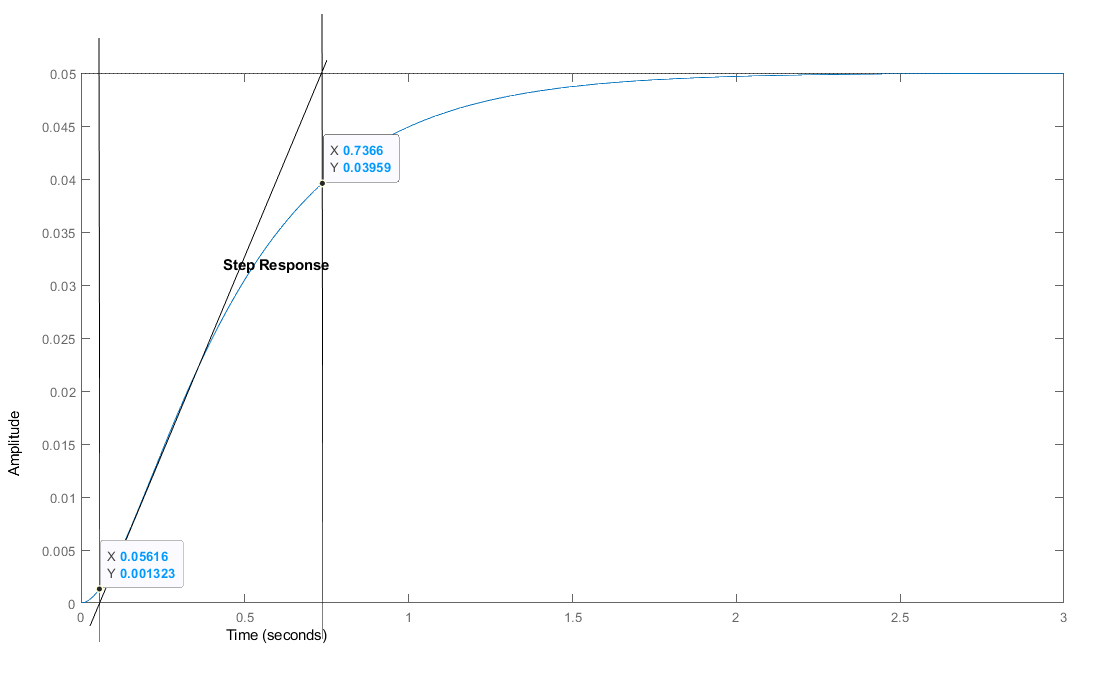

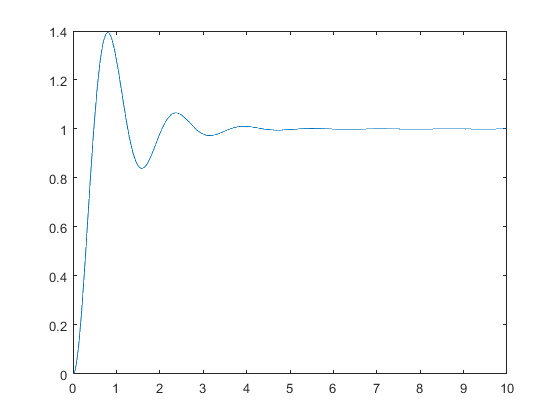

t = 0:0.01:10;
L = 0.05616;
K = 0.05;
T = 0.68049;    % 0.7366-0.05616
kp = round(1.2*T/L);   % 14.5404
ki = round(kp/(2*L));  %129.4550
kd = round(kp*L/2);    %0.4083
y2 = drawFitness(sys, kp,ki,kd, t);
plot(t,y2);

We have to use 8 bits to represent Kp, Ki, Kd values.

## Evolution steps

fprintf("Generation %d \n",0);

Generation 0 


newPop = pop;

Unrecognized function or variable 'pop'.

max_fitness = max(newPop(4,:));
avg_fitness = mean(newPop(4,:));

fprintf("Fitness max : %f, avg : %f \n",max_fitness, avg_fitness);

for i=1:num_of_evolutions
    fprintf("Generation %d \n",i);
    newPop = generateNewPopulation(newPop, sys);
    
    max_fitness = max(newPop(4,:));
    avg_fitness = mean(newPop(4,:));
    
    fprintf("Fitness max : %f, avg : %f \n",max_fitness, avg_fitness);
end

## drawing

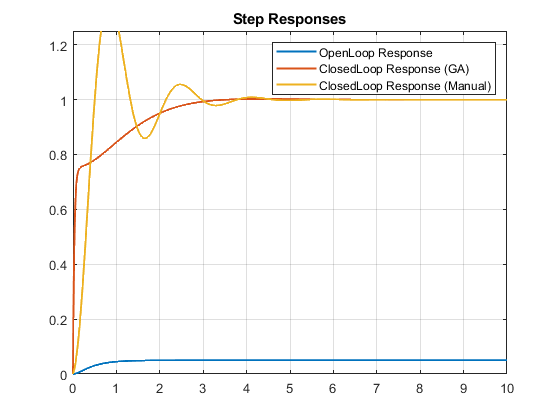

t = 0:0.01:10;
y0 = step(sys,t);

best_fitness = max(newPop(4,:));
best_fitness_index = find(newPop(4,:) == best_fitness);

y1 = drawFitness(sys, pop(1,best_fitness_index),pop(2,best_fitness_index),pop(3,best_fitness_index), t);

% draw response for manual kp,ki,kd values

kp = 14.5404;
ki = 129.4550;
kd = 0.4083;


y2 = drawFitness(sys, kp,ki,kd, t);

figure;
plot(t, y0, 'LineWidth', 1.5);
hold on
plot(t, y1, 'LineWidth', 1.5);
hold off
hold on
plot(t, y2, 'LineWidth', 1.5);
hold off
title('Step Responses');

axis([0 10 0 1.25]);
legend('OpenLoop Response', 'ClosedLoop Response (GA)', 'ClosedLoop Response (Manual)');
grid on;